clear; clf; clc;
load('YOLOv2Detector.mat')
digitalDataSetPath = 'C:\Users\its_a\OneDrive\Documents\Lab\Code\BEAMS\Image Processing\Train';
truth = readmatrix('C:\Users\its_a\OneDrive\Documents\Lab\Code\BEAMS\Image Processing\Train\train(1).csv');
imds = imageDatastore(digitalDataSetPath, 'IncludeSubfolders', false, 'LabelSource','foldernames');
sample1 = imds.Files;
shuffledIndices = randperm(length(sample1));
idx = floor(length(shuffledIndices));
imgds = imageDatastore(sample1(shuffledIndices(1:idx), :));
boxes = zeros(numel(imgds.Files), 4); 
acc = zeros(numel(imgds.Files), 1);
for i = 1:numel(imgds.Files)
    
    % Read the image
    J = readimage(imgds, i);
    
    % Run the detector.
    [bboxes,scores] = detect(detector,J, 'Threshold', 0.6);
    if (~isempty(bboxes))
    % Collect the results in the results table
        boxes(i, :) = bboxes(1,:);
        acc(i, :) = scores(1);
        imshow(imgds.Files{i});
        hold on
        rectangle('Position', bboxes(1,:), 'LineWidth', 2, 'EdgeColor', 'b')
        hold off
        rectangle('Position', truth(shuffledIndices(i),:), 'LineWidth', 2, 'EdgeColor', 'r')
        hold off
    end
end
avgAcc = mean(mean(acc))

clear; clf; clc;
load('YOLOv2Detector.mat')
videoFile = 'test2.avi';
reader = VideoReader(videoFile);
box_size = 95;
video_height = reader.Height;
video_width = reader.Width;
box_x_idx = 1:5:(video_width-box_size);
box_y_idx = 1:5:(video_height-box_size); 
box_frame = zeros(1, 2);
particle_box = detectBox(reader, box_x_idx, box_y_idx, box_size, detector, box_frame);
reader = VideoReader(videoFile);
videoPlayer = vision.VideoPlayer();
u = 1;
v = VideoWriter('videoMarked.avi');
v.FrameRate = reader.FrameRate;
open(v)
while hasFrame(reader)
    frame = readFrame(reader);
    I = insertMarker(frame, [particle_box(u,1) particle_box(u,2)], 'star', 'color', 'red', 'Size', 2);
    videoPlayer.step(I)
    u = u + 1;
    writeVideo(v, I);
end
close(v)
pos = particle_box;
pos = (190/2048).*pos; 
save('pos.mat', 'pos')

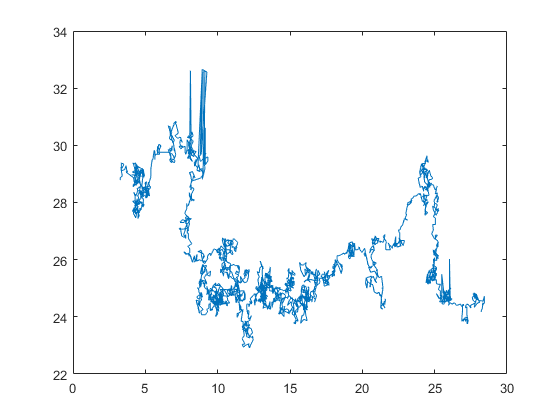

pos = cell2mat(struct2cell(load('pos.mat')));
pos(~any(pos,2), :) = [];
plot(pos(:,1), pos(:,2))

videoFile = 'test2.avi';
reader = VideoReader(videoFile);
total = floor(reader.Duration)-5; % Number of seconds in video
tau = zeros(1, total); % Empty array of time step intervals
msdX = zeros(1, total); % Empty array of msd in x-direction
msdY = zeros(1, total); % Empty array of msd in y-direction
msd = zeros(1, total); % Empty array of msd for x and y
a = 1; % a = how many seconds apart we are taking measurements (Δt) 
for b = 2:total
    dt = round(a*reader.FrameRate); % equate time step to # of frames
    tau(b) = a; 
    t = 125:dt:length(pos); % index of every ath second
    mean_squareX = zeros(length(t), 1);
    mean_squareY = zeros(length(t), 1);
    for c = 1:length(t)-1
        mean_squareX(c) = (pos(t(c+1),1) - pos(t(c), 1))^2; 
        mean_squareY(c) = (pos(t(c+1),2) - pos(t(c), 2))^2; 
    end    
    msdX(b) = sum(mean_squareX)/length(mean_squareX);
    msdY(b) = sum(mean_squareY)/length(mean_squareY);
    msd(b) = sum(mean_squareX + mean_squareY)/(length(t)-1); 
    a = a + 1; 
end
figure
plot(tau, msd)
hold on
xlabel('t (seconds)')
ylabel('msd (um^2)')
title('msd vs time')
p = polyfit(tau, msd, 1);
Y = polyval(p, tau);
plot(tau, Y)
hold off
D = (p(1)/2)*1e-12; 
kb = physconst('Boltzmann');
T = 23+273;
r = 1e-6;
n = kb*T*1000/(6*pi*D*r);
fprintf('n = %.3f mPa*s', n)

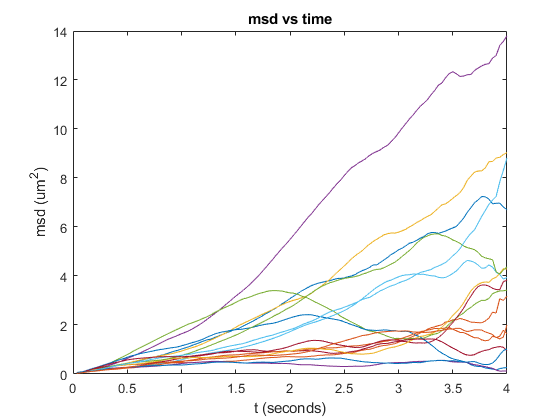

clear;
pos = cell2mat(struct2cell(load('pos3.mat')));
pos(~any(pos,2), :) = [];
videoFile = 'videoMarked.avi';
reader = VideoReader(videoFile);
N = length(pos);
frameRate = round(reader.FrameRate);
intrvl = 4;
rate = (frameRate * intrvl)+1;
w = 0:rate-1:N; 
for r = 1:length(w)-6
   for n = 1:rate-1
       sum = 0;
       m = rate-n;
       for i = 1:m
           sum = sum + (pos(i+w(r)+n, 1)-(pos(i+w(r), 1)))^2 + (pos(i+w(r)+n, 2) - pos(i+w(r),2))^2; 
       end
       msd(n) = sum/m;
   end
   msdTotal(r,:) = msd; 
end
tau = (1:rate-1)./frameRate;
avgMSD = mean(msdTotal); 
plot(tau, msdTotal')
xlabel('t (seconds)')
ylabel('msd (um^2)')
title('msd vs time')

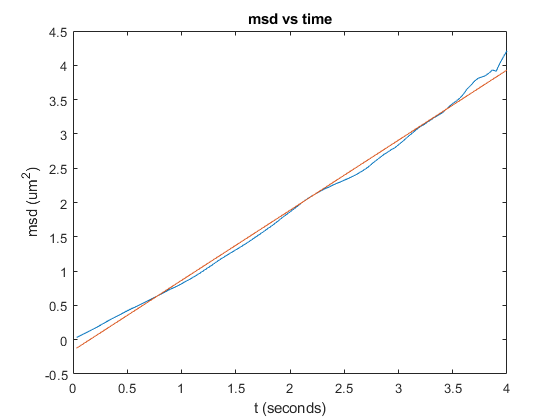

plot(tau, avgMSD, 'DisplayName', 'avgMSD')
hold on
xlabel('t (seconds)')
ylabel('msd (um^2)')
title('msd vs time')

p = polyfit(tau, avgMSD, 1);
Y = polyval(p, tau);
plot(tau, Y)
hold off

D = (p(1)/4)*1e-12; 
kb = physconst('Boltzmann');
T = 23+273;
r = 1e-6;
n = kb*T*1000/(6*pi*D*r);
fprintf('n = %.3f mPa*s', n)

n = 0.848 mPa*s